# Evaluate an LSTM Network

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data and corresponding labels, transforms the datastore, and extracts the testing data.

pathToSignals = "../data/flooddata";
rng default
sigds = signalDatastore(pathToSignals, ...
                        "IncludeSubfolders", true, ...
                        "SignalVariableNames", ["ax" "ay" "az"], ...
                        "ReadOutputOrientation", "row");
labels = folders2labels(pathToSignals);
labels = renamecats(labels, ["0.0 ft" "0.19 ft" "2.5 ft" "4.5 ft"]);
sigt = transform(sigds, @prepsig);
sigdata = readall(sigt);
idx = splitlabels(labels, [0.8 0.1]);
testdata = sigdata(idx{3});
testlabels = labels(idx{3});

Load the trained network.

load ./floodnet.mat

## Task 1

In this activity, you will evaluate the trained LSTM using the test data set. The `classify` function can be used with an trained LSTM to predict the class of new signals.

`predictedLabel` `=` `classify``(``net``,``data``)`

The testing data and corresponding labels are stored in `testdata` and `testlabels`.

testpred = classify(floodnet, testdata)

testpred = 21×1 categorical array
     4.5 ft 
     4.5 ft 
     2.5 ft 
     4.5 ft 
     4.5 ft 
     4.5 ft 
     4.5 ft 
     4.5 ft 
     2.5 ft 
     2.5 ft 
     2.5 ft 
     4.5 ft 
     4.5 ft 
     4.5 ft 
     4.5 ft 
     4.5 ft 
     4.5 ft 
     4.5 ft 
     4.5 ft 
     4.5 ft 
     4.5 ft 


## Task 2

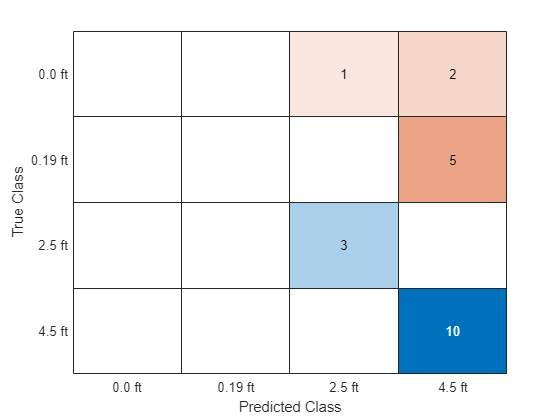

confusionchart(testlabels, testpred)

function sig = prepsig(sigin)
    sig = cell2mat(sigin);
    sig = sig';
    sig = {sig};
end